# Control Water Level in a Tank Using a DDPG Agent

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


open_system("rlwatertank")

% Observation info
obsInfo = rlNumericSpec([3 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');

% Name and description are optional and not used 
% by the software
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error," + ... 
    " and measured height";

% Action info
actInfo = rlNumericSpec([1 1]);
actInfo.Name = "flow";

env = rlSimulinkEnv("rlwatertank","rlwatertank/RL Agent",...
    obsInfo,actInfo);
env.ResetFcn = @localResetFcn;

Ts = 1.0;
Tf = 200;
rng(0)

## Create the Critic

% Observation path
obsPath = featureInputLayer(obsInfo.Dimension(1), ...
    Name="obsInLyr");

% Action path
actPath = featureInputLayer(actInfo.Dimension(1), ...
    Name="actInLyr");

% Common path
commonPath = [
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(25)
    reluLayer()
    fullyConnectedLayer(25)
    reluLayer()
    fullyConnectedLayer(1,Name="QValue")
    ];

% Create the network object and add the layers
criticNet = dlnetwork();
criticNet = addLayers(criticNet,obsPath);
criticNet = addLayers(criticNet,actPath);
criticNet = addLayers(criticNet,commonPath);

% Connect the layers
criticNet = connectLayers(criticNet, ...
    "obsInLyr","concat/in1");
criticNet = connectLayers(criticNet, ...
    "actInLyr","concat/in2");

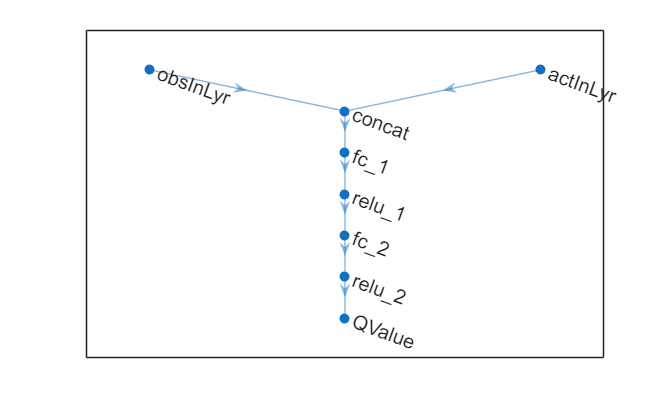

plot(criticNet) 

rng(0,"twister");
criticNet = initialize(criticNet);
summary(criticNet)


   Initialized: true

   Number of learnables: 801

   Inputs:
      1   'obsInLyr'   3 features
      2   'actInLyr'   1 features



critic = rlQValueFunction(criticNet, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr");

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
-0.4320

## Create the Actor

actorNet = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(25)
    reluLayer()
    fullyConnectedLayer(25)
    reluLayer()
    fullyConnectedLayer(actInfo.Dimension(1))
    ];

rng(0,"twister");
actorNet = dlnetwork(actorNet);
summary(actorNet)


   Initialized: true

   Number of learnables: 776

   Inputs:
      1   'input'   3 features



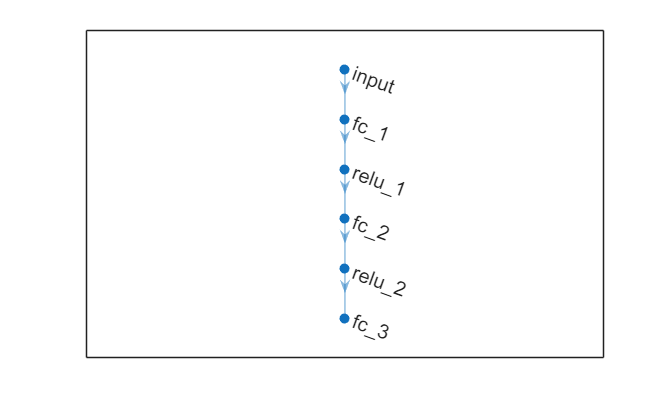

plot(actorNet)

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);
getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.1002]}


##  DDPG Agent

agent = rlDDPGAgent(actor,critic);

agent.AgentOptions.SampleTime = Ts;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 400;
agent.AgentOptions.ExperienceBufferLength = 1e6;

actorOpts = rlOptimizerOptions( ...
    LearnRate=1e-5, ...
    GradientThreshold=1);
criticOpts = rlOptimizerOptions( ...
    LearnRate=1e-4, ...
    GradientThreshold=1);
agent.AgentOptions.ActorOptimizerOptions = actorOpts;
agent.AgentOptions.CriticOptimizerOptions = criticOpts;

agent.AgentOptions.NoiseOptions.StandardDeviation = 0.1;
agent.AgentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-4;

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.1015]}


## Train Agent

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=500, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    Plots="training-progress", ...
    Verbose=false, ...
    StopTrainingCriteria="EvaluationStatistic", ...
    StopTrainingValue=2000);

% agent evaluator
evl = rlEvaluator(EvaluationFrequency=10,NumEpisodes=5);

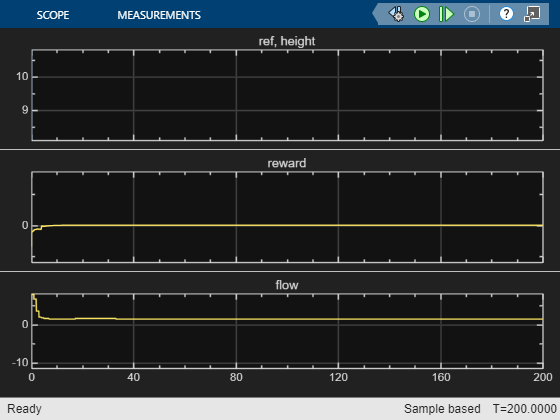

rng(0,"twister");

doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
else
    % Load the pretrained agent for the example.
    load("WaterTankDDPG.mat","agent")
end

## Validate Trained Agent

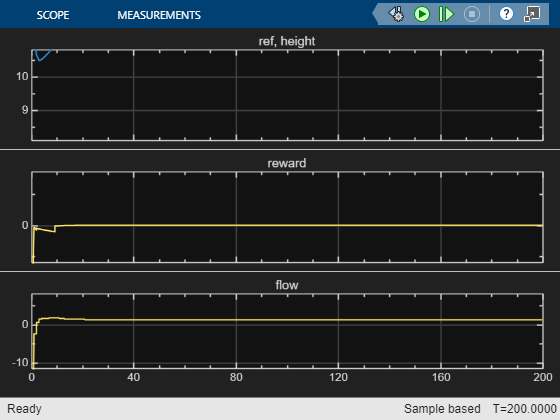

rng(0,"twister");
simOpts = rlSimulationOptions( ...
    MaxSteps=ceil(Tf/Ts), ...
    StopOnError="on");
experiences = sim(env,agent,simOpts);

rng(previousRngState);


## Local Reset Function

function in = localResetFcn(in)

    % ✅ Use fixed setpoint from workspace
    blk = sprintf("rlwatertank/Desired \nWater Level");
    setpoint = evalin('base', 'desiredLevel');  % Grab from base workspace
    in = setBlockParameter(in, blk, Value=num2str(setpoint));

    % ✅ Randomize initial tank height
    h = 3*randn + 10;
    while h <= 0 || h > 50
        h = 3*randn + 10;
    end
        % 🔁 Save this height for PI to use
    assignin('base', 'initialHeight', h);

    blk = "rlwatertank/Water-Tank System/H";
    in = setBlockParameter(in, blk, InitialCondition=num2str(h));

end

save('MLtrained.mat', 'agent', 'env');
